clear;
clf;

phi = @(x) -cos(x); true = @(x) cos(x);
% phi = @(x) cos(2*x); true = @(x) -4*cos(2*x);

M = 9;
N = 10*2.^(0:M);

cell_cpu = cell(M+1, 4);
cell_err = cell(M+1, 4);
cell_err_max = cell(M+1, 4);
cell_grid = cell(M+1);

for i = 1:M+1
    n = N(i);
    h = 2*pi/n;
    x = h*(1:n)';
    cell_grid{i} = x;

    % first order derivative (centered) twice
    tic;
    c = [0 -1 zeros(1,n-2)]'; 
    r = [0  1 zeros(1,n-2)];
    SD = toeplitz(c,r);
    SD(1,n) = -1;
    SD(n,1) =  1;
    SD = SD/(2*h);
    SD2 = SD*SD;
    cell_cpu{i,1} = toc;
    
    err_SD2 = SD2*phi(x) - true(x);
    cell_err{i,1} = err_SD2;
    cell_err_max{i,1} = max(err_SD2);

    % second order derivative (centered)
    tic;
    c = [-2 1 zeros(1,n-2)];
    TD = toeplitz(c);
    TD(1,n) = 1;
    TD(n,1) = 1;
    TD = TD/h^2;
    cell_cpu{i,2} = toc;
    
    err_TD = TD*phi(x) - true(x);
    cell_err{i,2} = err_TD;
    cell_err_max{i,2} = max(err_TD);

    % spectral differentiation (explicit)
    tic;
    c = [0 .5*(-1).^(1:n-1).*cot((1:n-1)*h/2)];
    SpecD = toeplitz(c, c([1 n:-1:2]));
    SpecD = SpecD*SpecD;
    W = SpecD*phi(x);
    cell_cpu{i,3} = toc;

    err_SpecD = W - true(x);
    cell_err{i,3} = err_SpecD;
    cell_err_max{i,3} = max(err_SpecD);

    % spectral differentiation (FFT)
    tic;
    U = fft(phi(x));    
    W1 = (ifft(1i*[0:n/2-1 0 1-n/2:-1]'.*U)); % diff wrt x
    W2 = (ifft(-[0:n/2 1-n/2:-1]'.^2.*U)); % second diff wrt x
    cell_cpu{i,4} = toc;
    
    err_FFT = W2 - true(x);
    cell_err{i,4} = err_FFT;
    cell_err_max{i,4} = max(err_FFT);
end

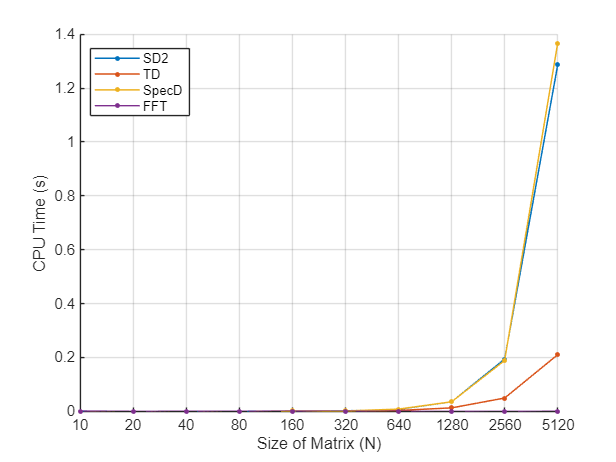

% plotting
xx = 1:M+1;
labels = cell(1,M+1);
for i = 1:M+1
    labels{1,i} = sprintf('%d', N(i));
end

figure();
legend('Location', 'best');
grid on;

xlabel('Size of Matrix (N)');
xticks(1:M+1);
xticklabels(labels);
ylabel('CPU Time (s)');

hold on;
plot(xx', [cell_cpu{:,1}], '.-', 'MarkerSize', 10, 'LineWidth', 1, 'Color', "#0072BD", ...
    'DisplayName', 'SD2');
plot(xx', [cell_cpu{:,2}], '.-', 'MarkerSize', 10, 'LineWidth', 1, 'Color', "#D95319", ...
    'DisplayName', 'TD');
plot(xx', [cell_cpu{:,3}], '.-', 'MarkerSize', 10, 'LineWidth', 1, 'Color', "#EDB120", ...
    'DisplayName', 'SpecD');
plot(xx', [cell_cpu{:,4}], '.-', 'MarkerSize', 10, 'LineWidth', 1, 'Color', "#7E2F8E", ...
    'DisplayName', 'FFT');

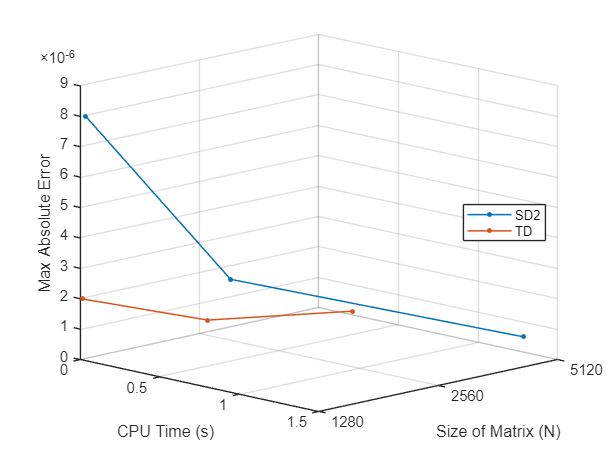

figure();
view([45 15]);
legend('Location', 'east');
grid on;

xlabel('CPU Time (s)');
ylabel('Size of Matrix (N)');
yticks(1:M+1);
yticklabels(labels);
zlabel('Max Absolute Error');

strt = 8;

hold on;
plot3([cell_cpu{strt:end,1}], xx(strt:end), [cell_err_max{strt:end,1}], '.-', ...
    'MarkerSize', 10, 'LineWidth', 1, 'Color', "#0072BD", 'DisplayName', 'SD2');
plot3([cell_cpu{strt:end,2}], xx(strt:end), [cell_err_max{strt:end,2}], '.-', ...
    'MarkerSize', 10, 'LineWidth', 1, 'Color', "#D95319", 'DisplayName', 'TD');

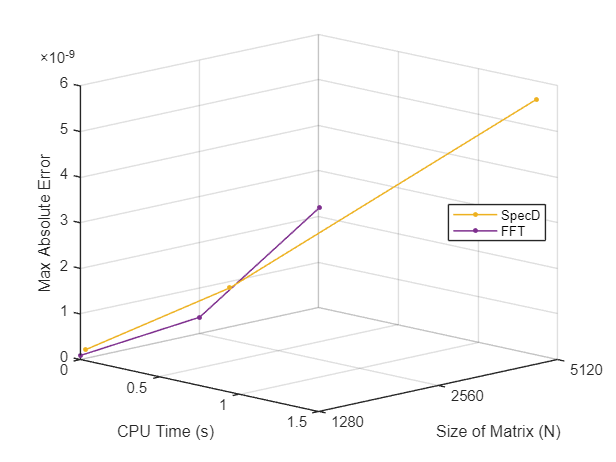

figure();
view([45 15]);
legend('Location', 'east');
grid on;

xlabel('CPU Time (s)');
ylabel('Size of Matrix (N)');
yticks(1:M+1);
yticklabels(labels);
zlabel('Max Absolute Error');

strt = 8;

hold on;
plot3([cell_cpu{strt:end,3}], xx(strt:end), [cell_err_max{strt:end,3}], '.-', ...
    'MarkerSize', 10, 'LineWidth', 1, 'Color', "#EDB120", 'DisplayName', 'SpecD');
plot3([cell_cpu{strt:end,4}], xx(strt:end), [cell_err_max{strt:end,4}], '.-', ...
    'MarkerSize', 10, 'LineWidth', 1, 'Color', "#7E2F8E", 'DisplayName', 'FFT');